format long
k1 = 5

k1 =      5


k2 = 0.5

k2 =    0.500000000000000


k3 = 0.5

k3 =    0.500000000000000


k4 = 5

k4 =      5


tspan = [0,4]

tspan =      0     4


ya = [12;4]

ya =     12
     4


n = 10000

n =        10000


nmax = 10

nmax =     10


tol = 10E-9

tol =      1.000000000000000e-08


f = @(t,y) [k1*y(1) - k2*y(1)*y(2) ; k3*y(1)*y(2) - k4*y(2)]

f = function_handle with value:
    @(t,y)[k1*y(1)-k2*y(1)*y(2);k3*y(1)*y(2)-k4*y(2)]


df = @(t,y) [k1-k2*y(2), -k2*y(1) ; k3*y(2), k3*y(1)-k4]

df = function_handle with value:
    @(t,y)[k1-k2*y(2),-k2*y(1);k3*y(2),k3*y(1)-k4]


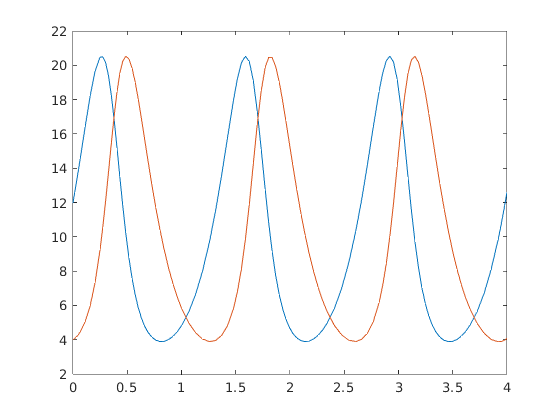

[t,y] = ode45(f,tspan,ya);
plot(t,y)

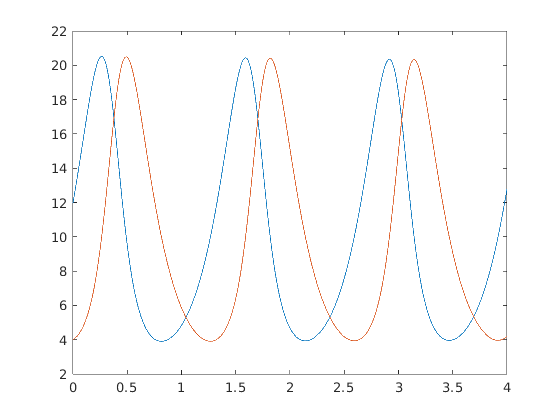

[t_e, y_e] = impl_euler(f,tspan,ya,n,df,tol,nmax);
plot(t_e,y_e)



f = @(t,y) diag([1,2])*y;
df = @(t,y) diag([1,2]);
tol=1e-12; nmax=100;
[t,y] = impl_euler(f, [0,0.1], [10;20], 1, df, tol, nmax)

t =                    0
   0.100000000000000


y =   10.000000000000000  20.000000000000000
  11.111111111111111  25.000000000000000
